# Hankel Matrix Completion

## Experimenting with LTI's without input

First we get an intuition of state space definition without input. We deal with discrete systems, since we are interested in data sampled at specific time points in history.

% statenum states, outputnum outputs, 0 input
statenum = 100;
outputnum = 1;

state_space = drss(statenum,outputnum,0)

state_space =
 
  A = 
                 x1          x2          x3          x4          x5          x6          x7          x8          x9         x10         x11         x12         x13         x14         x15         x16         x17         x18         x19         x20         x21         x22         x23         x24         x25         x26         x27         x28         x29         x30         x31         x32         x33         x34         x35         x36         x37         x38         x39         x40         x41         x42         x43         x44         x45         x46         x47         x48         x49         x50         x51         x52         x53         x54         x55         x56         x57         x58         x59         x60         x61         x62         x63         x64         x65         x66         x67         x68         x69         x70         x71         x72         x73         x74         x75         x76         x77         x78         x79         x80         x

dssprop(state_space)

State-space properties: 
    "Number of states: 100"
    "Number of inputs: 0"
    "Number of outputs: 1"

State-space dimensions: 
    "A_rows:100"    "A_cols:100"
    "B_rows:100"    "B_cols:0"  
    "C_rows:1"      "C_cols:100"
    "D_rows:1"      "D_cols:0"  

Max absolute eigen value: 1
Eigen values of A: 
    0.9421
    0.9421
    0.9079
    0.9079
    1.0000
    0.9291
    0.9353
    0.9691
    0.9761
    0.8994
    0.9934
    0.9934
    0.6856
    0.6856
    0.7460
    0.7460
    0.8583
    0.8226
    0.7653
    0.7653
    0.7700
    0.6326
    0.6326
    0.5379
    0.5379
    0.6594
    0.6940
    0.6438
    0.6181
    0.6037
    0.6299
    0.5039
    0.5039
    0.5846
    0.6216
    0.6129
    0.5691
    0.5925
    0.5820
    0.3884
    0.3884
    0.3652
    0.3652
    0.5277
    0.4664
    0.4664
    0.4901
    0.4957
    0.4638
    0.4434
    0.4386
    0.4314
    0.4246
    0.4166
    0.4053
    0.4248
    0.3909
    0.4022
    0.2745
    0.2745
    0.3758
    0.3419
    0

Now we create a set of outputs, with x(0) = x_0 != 0 (since we dont have an input and thus if the state is the zero vector the transfer function will not do anything to the state)

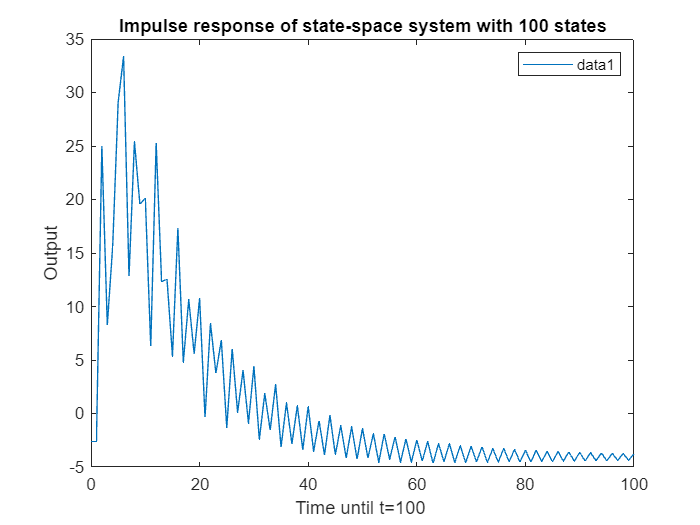

maxTime = 100;

figure;
dssplot(state_space,maxTime);

Notice that its possible for one of the eigenvalues to be exactly 1, which is neither stable nor unstable (marginally stable). Using the drss function we can generate many different kinds of discrete-time state-space systems that are stable. In the plot we observe that after a large enough T the impulse response stabilizes.

## Experimenting with LTI's with input

We can also generate an LTI with an input vector upon which a transformation B and D have an effect on the state change and output. We can have a single-input or multi-input.

% statenum states, outputnum outputs, inputnum input
statenum = 100;
outputnum = 4;
inputnum = 4;
maxTime = 100;
input = [2;1;2;3];


state_space = drss(statenum,outputnum,inputnum)

state_space =
 
  A = 
                 x1          x2          x3          x4          x5          x6          x7          x8          x9         x10         x11         x12         x13         x14         x15         x16         x17         x18         x19         x20         x21         x22         x23         x24         x25         x26         x27         x28         x29         x30         x31         x32         x33         x34         x35         x36         x37         x38         x39         x40         x41         x42         x43         x44         x45         x46         x47         x48         x49         x50         x51         x52         x53         x54         x55         x56         x57         x58         x59         x60         x61         x62         x63         x64         x65         x66         x67         x68         x69         x70         x71         x72         x73         x74         x75         x76         x77         x78         x79         x80         x

dssprop(state_space)

State-space properties: 
    "Number of states: 100"
    "Number of inputs: 4"
    "Number of outputs: 4"

State-space dimensions: 
    "A_rows:100"    "A_cols:100"
    "B_rows:100"    "B_cols:4"  
    "C_rows:4"      "C_cols:100"
    "D_rows:4"      "D_cols:4"  

Max absolute eigen value: 1
Eigen values of A: 
    0.9348
    0.9348
    0.8950
    0.8950
    0.8656
    0.8656
    0.8129
    0.8129
    0.7808
    0.7808
    0.9014
    0.9014
    0.9235
    0.9983
    0.9724
    0.9625
    0.9195
    0.9407
    0.7209
    0.7209
    0.8999
    0.8813
    1.0000
    1.0000
    0.7869
    0.6473
    0.6473
    0.6826
    0.6826
    0.7742
    0.7566
    0.7578
    0.6919
    0.5606
    0.5606
    0.5635
    0.5635
    0.6991
    0.5341
    0.5341
    0.6558
    0.4918
    0.4918
    0.6451
    0.5121
    0.5121
    0.6092
    0.5435
    0.5367
    0.5298
    0.5123
    0.5604
    0.4801
    0.5564
    0.3696
    0.3696
    0.4432
    0.4705
    0.3758
    0.3758
    0.3146
    0.3146
    0

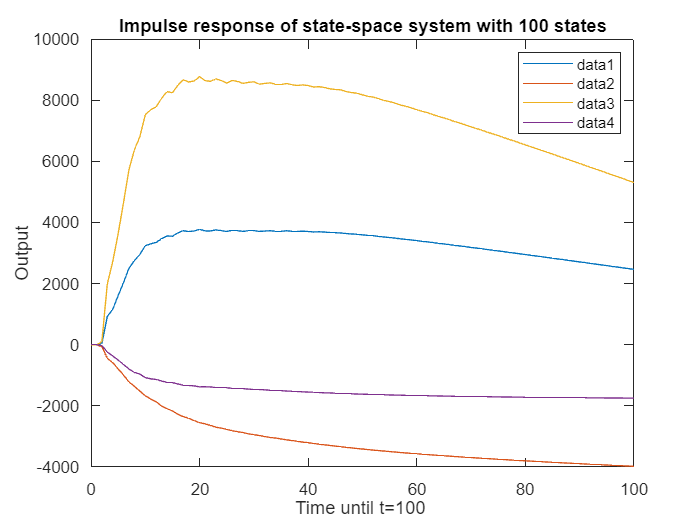

figure;
dssplot(state_space,maxTime,input);

Lets plot the trajectory of the impulse response with the old input and some new input.

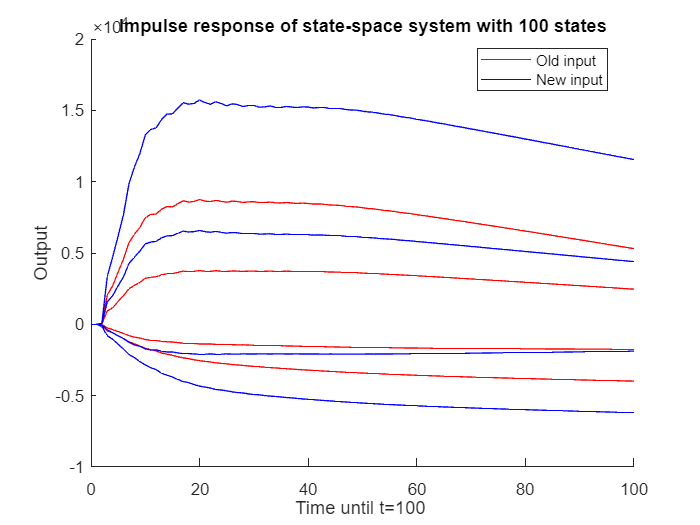

figure;
hold on
f1 = dssplot(state_space,maxTime,input);
f2 = dssplot(state_space,maxTime,[2;1;5;6]);
set(f1, 'Color', 'r');
set(f2, 'Color', 'b');
legend([f1(1), f2(1)], {'Old input', 'New input'}, 'Location', 'best');
hold off;

## Experimenting with Hankel Matrices

Now we're going to experiment with hankel matrices and show how it is relevant to time-series data.  Firstly, we create a drss and with a single in- and output and random initial conditions. We then convert the output to a hankel matrix.

input = 2;
inputnum = 1;
outputnum = 1; 
statenum = 3;
maxTime = 50;

dss = drss(statenum, outputnum, inputnum)

dss =
 
  A = 
             x1        x2        x3
   x1  0.006037    -2.275     2.692
   x2    0.5463    -3.978     4.331
   x3     0.679    -2.923     2.959
 
  B = 
            u1
   x1        0
   x2  -0.9096
   x3   0.6353
 
  C = 
            x1       x2       x3
   y1  -0.7899  -0.9464  -0.9964
 
  D = 
       u1
   y1   0
 
Sample time: unspecified
Discrete-time state-space model.


[x,y] = dsssim(dss,maxTime,input)

x =     0.0120    0.8397    6.6609    3.7175    4.9544    4.3730    4.6966    4.4985    4.6233    4.5443    4.5942    4.5628    4.5826    4.5701    4.5780    4.5730    4.5761    4.5742    4.5754    4.5746    4.5751    4.5748    4.5750    4.5749    4.5750    4.5749    4.5749    4.5749    4.5749    4.5749    4.5749    4.5749    4.5749    4.5749    4.5749    4.5749    4.5749    4.5749    4.5749    4.5749    4.5749    4.5749    4.5749    4.5749    4.5749    4.5749    4.5749    4.5749    4.5749    4.5749
    0.7799   -0.7098    9.5737    4.6913    6.6546    5.7584    6.2521    5.9500    6.1407    6.0200    6.0962    6.0482    6.0785    6.0594    6.0714    6.0638    6.0686    6.0656    6.0675    6.0663    6.0670    6.0666    6.0669    6.0667    6.0668    6.0667    6.0668    6.0667    6.0668    6.0667    6.0667    6.0667    6.0667    6.0667    6.0667    6.0667    6.0667    6.0667    6.0667    6.0667    6.0667    6.0667    6.0667    6.0667    6.0667    6.0667    6.0667    6.0667    6.0667    6

y =    -1.7150   -1.7150   -1.8574  -23.7446  -13.1521  -17.4224  -15.4814  -16.5459  -15.8958  -16.3059  -16.0462  -16.2103  -16.1069  -16.1720  -16.1310  -16.1568  -16.1405  -16.1508  -16.1443  -16.1484  -16.1458  -16.1475  -16.1464  -16.1471  -16.1467  -16.1469  -16.1468  -16.1469  -16.1468  -16.1469  -16.1468  -16.1468  -16.1468  -16.1468  -16.1468  -16.1468  -16.1468  -16.1468  -16.1468  -16.1468  -16.1468  -16.1468  -16.1468  -16.1468  -16.1468  -16.1468  -16.1468  -16.1468  -16.1468  -16.1468


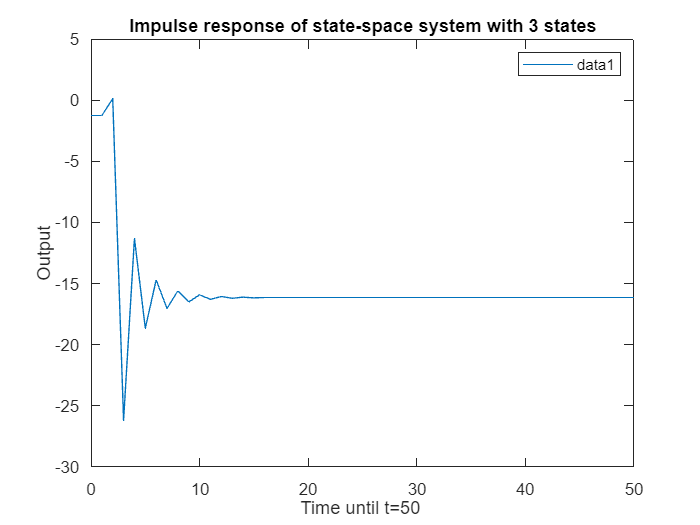

dssplot(dss,maxTime,input);

delta = 26

delta = 26

c = y(1,1:delta)

c =    -1.7150   -1.7150   -1.8574  -23.7446  -13.1521  -17.4224  -15.4814  -16.5459  -15.8958  -16.3059  -16.0462  -16.2103  -16.1069  -16.1720  -16.1310  -16.1568  -16.1405  -16.1508  -16.1443  -16.1484  -16.1458  -16.1475  -16.1464  -16.1471  -16.1467  -16.1469


r =y(1,delta:size(y,2))

r =   -16.1469  -16.1468  -16.1469  -16.1468  -16.1469  -16.1468  -16.1468  -16.1468  -16.1468  -16.1468  -16.1468  -16.1468  -16.1468  -16.1468  -16.1468  -16.1468  -16.1468  -16.1468  -16.1468  -16.1468  -16.1468  -16.1468  -16.1468  -16.1468  -16.1468  -16.1468


H = hankel(c,r)

H =    -1.7150   -1.7150   -1.8574  -23.7446  -13.1521  -17.4224  -15.4814  -16.5459  -15.8958  -16.3059  -16.0462  -16.2103  -16.1069  -16.1720  -16.1310  -16.1568  -16.1405  -16.1508  -16.1443  -16.1484  -16.1458  -16.1475  -16.1464  -16.1471  -16.1467  -16.1469
   -1.7150   -1.8574  -23.7446  -13.1521  -17.4224  -15.4814  -16.5459  -15.8958  -16.3059  -16.0462  -16.2103  -16.1069  -16.1720  -16.1310  -16.1568  -16.1405  -16.1508  -16.1443  -16.1484  -16.1458  -16.1475  -16.1464  -16.1471  -16.1467  -16.1469  -16.1468
   -1.8574  -23.7446  -13.1521  -17.4224  -15.4814  -16.5459  -15.8958  -16.3059  -16.0462  -16.2103  -16.1069  -16.1720  -16.1310  -16.1568  -16.1405  -16.1508  -16.1443  -16.1484  -16.1458  -16.1475  -16.1464  -16.1471  -16.1467  -16.1469  -16.1468  -16.1469
  -23.7446  -13.1521  -17.4224  -15.4814  -16.5459  -15.8958  -16.3059  -16.0462  -16.2103  -16.1069  -16.1720  -16.1310  -16.1568  -16.1405  -16.1508  -16.1443  -16.1484  -16.1458  -16.1475  -16.1464  -16.1471  -

We can also use our hankelizeM function for quick hankel matrix generation with a specific lag length.

H = hankelizeM(y,26)

H =    -1.7150   -1.7150   -1.8574  -23.7446  -13.1521  -17.4224  -15.4814  -16.5459  -15.8958  -16.3059  -16.0462  -16.2103  -16.1069  -16.1720  -16.1310  -16.1568  -16.1405  -16.1508  -16.1443  -16.1484  -16.1458  -16.1475  -16.1464  -16.1471  -16.1467  -16.1469
   -1.7150   -1.8574  -23.7446  -13.1521  -17.4224  -15.4814  -16.5459  -15.8958  -16.3059  -16.0462  -16.2103  -16.1069  -16.1720  -16.1310  -16.1568  -16.1405  -16.1508  -16.1443  -16.1484  -16.1458  -16.1475  -16.1464  -16.1471  -16.1467  -16.1469  -16.1468
   -1.8574  -23.7446  -13.1521  -17.4224  -15.4814  -16.5459  -15.8958  -16.3059  -16.0462  -16.2103  -16.1069  -16.1720  -16.1310  -16.1568  -16.1405  -16.1508  -16.1443  -16.1484  -16.1458  -16.1475  -16.1464  -16.1471  -16.1467  -16.1469  -16.1468  -16.1469
  -23.7446  -13.1521  -17.4224  -15.4814  -16.5459  -15.8958  -16.3059  -16.0462  -16.2103  -16.1069  -16.1720  -16.1310  -16.1568  -16.1405  -16.1508  -16.1443  -16.1484  -16.1458  -16.1475  -16.1464  -16.1471  -

We can change the lag length to create different dimensions of our hankel matrix

hankelizeM(y,10)

ans =    -1.7150   -1.7150   -1.8574  -23.7446  -13.1521  -17.4224  -15.4814  -16.5459  -15.8958  -16.3059  -16.0462  -16.2103  -16.1069  -16.1720  -16.1310  -16.1568  -16.1405  -16.1508  -16.1443  -16.1484  -16.1458  -16.1475  -16.1464  -16.1471  -16.1467  -16.1469  -16.1468  -16.1469  -16.1468  -16.1469  -16.1468  -16.1468  -16.1468  -16.1468  -16.1468  -16.1468  -16.1468  -16.1468  -16.1468  -16.1468  -16.1468  -16.1468
   -1.7150   -1.8574  -23.7446  -13.1521  -17.4224  -15.4814  -16.5459  -15.8958  -16.3059  -16.0462  -16.2103  -16.1069  -16.1720  -16.1310  -16.1568  -16.1405  -16.1508  -16.1443  -16.1484  -16.1458  -16.1475  -16.1464  -16.1471  -16.1467  -16.1469  -16.1468  -16.1469  -16.1468  -16.1469  -16.1468  -16.1468  -16.1468  -16.1468  -16.1468  -16.1468  -16.1468  -16.1468  -16.1468  -16.1468  -16.1468  -16.1468  -16.1468
   -1.8574  -23.7446  -13.1521  -17.4224  -15.4814  -16.5459  -15.8958  -16.3059  -16.0462  -16.2103  -16.1069  -16.1720  -16.1310  -16.1568  -16.1405  

hankelizeM(y,30)

ans =    -1.7150   -1.7150   -1.8574  -23.7446  -13.1521  -17.4224  -15.4814  -16.5459  -15.8958  -16.3059  -16.0462  -16.2103  -16.1069  -16.1720  -16.1310  -16.1568  -16.1405  -16.1508  -16.1443  -16.1484  -16.1458  -16.1475
   -1.7150   -1.8574  -23.7446  -13.1521  -17.4224  -15.4814  -16.5459  -15.8958  -16.3059  -16.0462  -16.2103  -16.1069  -16.1720  -16.1310  -16.1568  -16.1405  -16.1508  -16.1443  -16.1484  -16.1458  -16.1475  -16.1464
   -1.8574  -23.7446  -13.1521  -17.4224  -15.4814  -16.5459  -15.8958  -16.3059  -16.0462  -16.2103  -16.1069  -16.1720  -16.1310  -16.1568  -16.1405  -16.1508  -16.1443  -16.1484  -16.1458  -16.1475  -16.1464  -16.1471
  -23.7446  -13.1521  -17.4224  -15.4814  -16.5459  -15.8958  -16.3059  -16.0462  -16.2103  -16.1069  -16.1720  -16.1310  -16.1568  -16.1405  -16.1508  -16.1443  -16.1484  -16.1458  -16.1475  -16.1464  -16.1471  -16.1467
  -13.1521  -17.4224  -15.4814  -16.5459  -15.8958  -16.3059  -16.0462  -16.2103  -16.1069  -16.1720  -16.1310

We can view every row of the Hankel matrices as a sliding window over some data, which is why this offers insight into the inherent patterns and dynamics of the data/system. Once converted the data into this Hankel structure, it is possible to apply different decomposition techniques which we can then use e.g. in signal analysis to separate the main trend from noise. This structure and its sliding window over every row also offers contextual  features, which are important for forcasting and thus also relevant to our research.

## Experimenting with Hankel Matrix and making predictions

From here we can experiment with many different ways of predicting future outputs/points. 

### Hankel nuclear norm heuristic completion

We are now using the nuclear norm heuristic for completing the matrix as described in Dreesen, P., & Markovsky, I. (2019). Data-driven Simulation Using the Nuclear Norm Heuristic. *ICASSP, IEEE International Conference on Acoustics, Speech and Signal Processing - Proceedings*, *2019-May*. [https://doi.org/10.1109/ICASSP.2019.8682993.](https://doi.org/10.1109/ICASSP.2019.8682993.) We'll focus specifically on making future predictions

% Example time series data
data = sin(0.1 * (1:20))' + 0.05 * randn(20, 1);
dataLength = length(data);
L = 10;  % Number of lags (rows in the Hankel matrix)
N = dataLength - L + 1;  % Total columns in the Hankel matrix

% Create the full Hankel matrix without missing values initially
HankelMatrix = hankel(data(1:L), data(L:end));

% Define the number of points we want to predict (missing at the end)
numPredict = 1;

% Create a logical mask for the Hankel matrix with all ones (no missing data)
mask = true(size(HankelMatrix));

% Identify the columns in the Hankel matrix that correspond to the last 'numPredict' points
% These points appea5r in the last 'numPredict' rows of the last columns
for i = 1:numPredict
    mask(end-i+1, end-numPredict+i:end) = false;
end

% Now, apply the mask to set the last 'numPredict' points as NaN (missing)
HankelMatrix(~mask) = NaN;

% Display the mask and modified Hankel matrix to check
disp(mask);

   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   0



disp(HankelMatrix);

    0.0176    0.1634    0.2640    0.4001    0.5251    0.5454    0.7046    0.6315    0.7572    0.8070    0.9389
    0.1634    0.2640    0.4001    0.5251    0.5454    0.7046    0.6315    0.7572    0.8070    0.9389    0.9556
    0.2640    0.4001    0.5251    0.5454    0.7046    0.6315    0.7572    0.8070    0.9389    0.9556    1.0206
    0.4001    0.5251    0.5454    0.7046    0.6315    0.7572    0.8070    0.9389    0.9556    1.0206    0.9351
    0.5251    0.5454    0.7046    0.6315    0.7572    0.8070    0.9389    0.9556    1.0206    0.9351    1.0101
    0.5454    0.7046    0.6315    0.7572    0.8070    0.9389    0.9556    1.0206    0.9351    1.0101    0.9771
    0.7046    0.6315    0.7572    0.8070    0.9389    0.9556    1.0206    0.9351    1.0101    0.9771    1.0978
    0.6315    0.7572    0.8070    0.9389    0.9556    1.0206    0.9351    1.0101    0.9771    1.0978    1.0631
    0.7572    0.8070    0.9389    0.9556    1.0206    0.9351    1.0101    0.9771    1.0978    1.0631    1.0051
 

% Proceed with matrix completion using the nuclear norm minimization (using CVX)
cvx_begin sdp
    variable CompleteHankel(L, N)
    minimize(norm_nuc(CompleteHankel))
    subject to
        % Ensure the known entries remain the same
        CompleteHankel(mask) == HankelMatrix(mask);
cvx_end

 
Calling SDPT3 4.0: 232 variables, 109 equality constraints
------------------------------------------------------------

 num. of constraints = 109
 dim. of sdp    var  = 21,   num. of sdp  blk  =  1
 dim. of linear var  =  1
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|9.0e-01|1.3e+01|5.5e+03| 2.809636e+02  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.989|3.8e-08|2.4e-01|3.6e+02| 2.738856e+02  6.610129e+00| 0:0:00| chol  1  1 
 2|0.979|1.000|2.6e-08|1.0e-02|2.3e+01| 3.019268e+01  7.423624e+00| 0:0:00| chol  1  1 
 3|0.955|1.000|1.1e-08|1.0e-03|2.8e+00| 1.237387e+01  9.571455e+00| 0:0:00| chol  1  1 
 4|0.966|

% Check the completion status
disp(cvx_status);

Solved


% Extract the predicted values from the completed Hankel matrix
predictedValues = CompleteHankel(end, end-numPredict+1:end);
disp('Predicted values:');

Predicted values:


disp(predictedValues);

    0.9305



disp(transpose(data(end-numPredict+1:end)))

    0.9437



Results:

rmse(predictedValues,transpose(data(end-numPredict+1:end)))

ans = 0.0132

#### Notes on nuclear norm heuristic

- We can alternatively also try to compute the recurrence relation instead of solving the convex problem

- The most optimal value for L seems to be around when the lagged hankel matrix of the past trajectories H_L(w_d) is square

### Hankel alternative view of koopman

Check file ``i6220934_thesis_havok_experiments.mlx`` for more details